# 2 Zeit diskrete Signale

## 2.2 Faltung

x = [5 4 3 2 1];
u = [1 1 1];

y = faltung(x,u);

## 2.3 Formatierung von Graphen

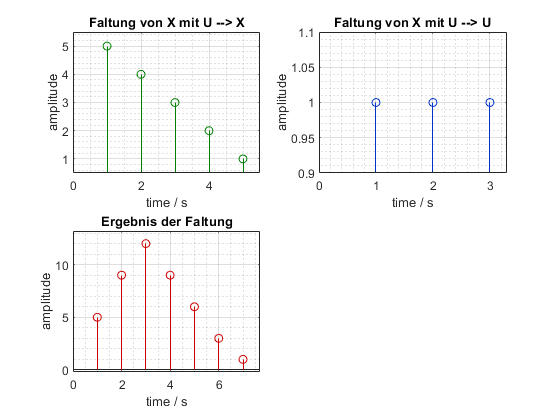

figure (1); 
subplot(2,2,1)
stem(x,'Color',[0 0.5 0])
stem_properties('Faltung von X mit U --> X','time / s','amplitude',x);

subplot(2,2,2)
stem(u,'Color',[0 0.2 0.8])
stem_properties('Faltung von X mit U --> U','time / s','amplitude',u);

subplot(2,2,3)
stem(y,'Color',[0.8 0 0])
stem_properties('Ergebnis der Faltung','time / s','amplitude',y);

## 2.4 Systemeigenschaften

nSymbols = 2^10;
rng(1)
data1 = randn(1, nSymbols);
rng(13)
data2 = randn(1, nSymbols);


#### Skalierer          y[k] = 2*x[k]

a = 2;
scaled_y1 = scaler(data1, a);
scaled_y2 = scaler(data2, a);

% Linearitätsprüfung (linear = 1)
isequal(scaled_y1 + scaled_y2 , scaler((data1+data2), a))

ans = logical
   1



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(scaled_y1, -t0);
eingang = scaler(circshift(data1, -t0), a);

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung



#### Offset             y[k] = x[k] + 1

o = 3;
offset_y1 = offset(data1, o);
offset_y2 = offset(data2, o);

% Linearitätsprüfung (linear = 1)
isequal(offset_y1 + offset_y2 , offset((data1+data2), o))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(offset_y1, -t0);
eingang = offset(circshift(data1, -t0), o);

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung




#### Zeitspiegelung    y[k] = x[-k]

mirror_y1 = flip(data1);
mirror_y2 = flip(data2);

% Linearitätsprüfung (linear = 1)
isequal(mirror_y1 + mirror_y2 , flip(data1+data2))

ans = logical
   1



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(mirror_y1, -t0);
eingang = flip(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   0



% Kausalitätsprüfung




#### Differenzenbildung y[k] = x[k]-x[k-1]

diff_y1 = difference(data1);
diff_y2 = difference(data2);

% Linearitätsprüfung (linear = 1)
isequal(diff_y1 + diff_y2 , difference(data1+data2))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(diff_y1, -t0);
eingang = difference(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   0



% Kausalitätsprüfung


#### Modulation         y[k] = x[k]*cos((pi/4)*k)

mod_y1 = 1

mod_y1 = 1

mod_y2 =1

mod_y2 = 1

#### Quantisierer       y[k] = gerundet(x[k])

quant_y1 = round(data1);
quant_y2 = round(data2);

% Linearitätsprüfung (linear = 1)
isequal(quant_y1 + quant_y2 , round(data1+data2))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(quant_y1, -t0);
eingang = round(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung





## 2.5 FIR-Systeme





%% 